%clear; clc;
mensajes = 10;
lambda = 1;
miu = 2;
rho = 0.5;

tiempoLlegada(1) = 0;
t = 1;
numMensajes = 0;

% Calcula las llegadas
while numMensajes < mensajes
    x = poissrnd(lambda);
    for i = 1 : x;
        tiempoLlegada(end + 1) = t;
    end
        
    numMensajes = numMensajes + x;
    t = t + 1;
end
tiempoLlegada = tiempoLlegada(2:end);

% Calcula los tiempos de servicio
for i = 1 : numMensajes
    tiempoServicio(i) = ceil(exprnd(miu)); 
end

% Calcula el tiempo de espera, de inicio, de salida y duración en el
% sistema
tiempoEspera(1) = 0;
tiempoInicio(1) = tiempoLlegada(1);
tiempoSalida(1) = tiempoLlegada(1) + tiempoServicio(1);
tiempoSistema(1) = tiempoServicio(1);
for i = 2 : numMensajes
    tiempoEspera(i) = max(0, tiempoSalida(i-1) - tiempoLlegada(i));
    tiempoInicio(i) = tiempoLlegada(i) + tiempoEspera(i);
    tiempoSalida(i) = tiempoLlegada(i) + tiempoEspera(i) + tiempoServicio(i);
    tiempoSistema(i) = tiempoSalida(i) - tiempoLlegada(i); 
end

% Obtiene el número de mensajes en el sistema en cada llegada
for i = 1 : numMensajes
   cont = 0;
   for j = 1 : i
       if tiempoSalida(j) > tiempoLlegada(i)
           cont = cont + 1; 
       end
   end
   numMensajesSistema(i) = cont;
end

% Crea la tabla y la exporta a un documento en Excel
tabla = table(tiempoLlegada.',tiempoServicio.', tiempoInicio.', tiempoSalida.',tiempoSistema.', tiempoEspera.', numMensajesSistema.', 'VariableNames', {'Llegada','Servicio','Inicio','Salida','Sistema','Espera','Mensajes'})

tabla = 11×7 table
    Llegada    Servicio    Inicio    Salida    Sistema    Espera    Mensajes
    _______    ________    ______    ______    _______    ______    ________

       1          3           1         4         3          0         1    
       2          2           4         6         4          2         2    
       5          2           6         8         3          1         2    
       5          2           8        10         5          3         3    
       7          3          10        13         6          3         3    
       8          3          13        16         8          5         3    
       8          1          16        17         9          8         4    
       9          1          17        18        

filename = 'tablaExamenFinal.xlsx'; 
writetable(tabla,filename,'Sheet',1,'Range','A1') 

t0 = tiempoInicio(1) 

t0 = 1

t1 = tiempoSalida(end)

t1 = 27

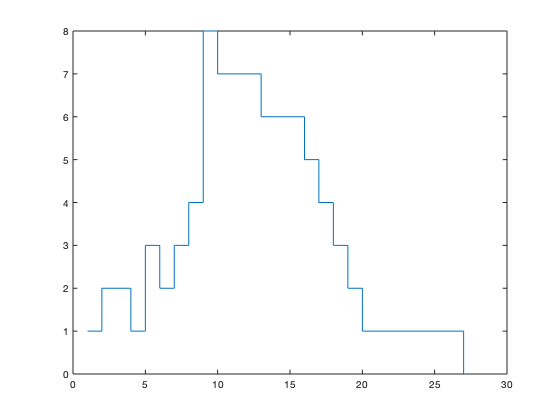

n = 1;
% Calcula los mensajes que hay por segundo
for t = t0 : t1 
   cont = 0;
   for j = 1 : numMensajes % Qué mensajes están activos
       if tiempoLlegada(j) <= t & tiempoSalida(j) > t
           cont = cont + 1; 
       end
   end
   tiempoMensajes(n) = cont;
   n = n + 1;
end

% Grafica el intervalo de 25 a 40
stairs(t0 : t1, tiempoMensajes);


% Sea tMax el último tiempo de llegada
tMax = tiempoLlegada(end);

% Promedios
promMensajes = sum(tiempoSistema)/tMax

promMensajes = 9.5556

promTiempoSistema =  sum(tiempoSistema)/numMensajes

promTiempoSistema = 7.8182


% Esperanzas
esperanzaN = (rho^2) / (1 - rho)

esperanzaN = 0.5000

esperanzaT = rho / (miu - lambda)

esperanzaT = 0.5000


% Probabilidades
prob0 = 1 - rho

prob0 = 0.5000

prob1 = prob0 * rho

prob1 = 0.2500

prob2 = prob0 * (rho^2)

prob2 = 0.1250


% <lambda> = llegadas / t
tasaPromLlegadas = numMensajes / tMax

tasaPromLlegadas = 1.2222


% La fórmula de Little nos dice que N = <lambda> * T
nLittle = tasaPromLlegadas * promTiempoSistema

nLittle = 9.5556